
%#ok<*CLALL>

clear all;clc 

syms mu a b c

eqns = [ ...
    2*a*mu+b; ...
    a+b+c; ...
    a*mu^2+b*mu+c-1]; 
sol = solve(eqns==0, [a; b; c]); 

sol.a

$$ans = -\frac{1}{\mu^{2}-2\,\mu +1}$$

sol.b

$$ans = \frac{2\,\mu }{\mu^{2}-2\,\mu +1}$$

sol.c

$$ans = -\frac{2\,\mu -1}{\mu^{2}-2\,\mu +1}$$

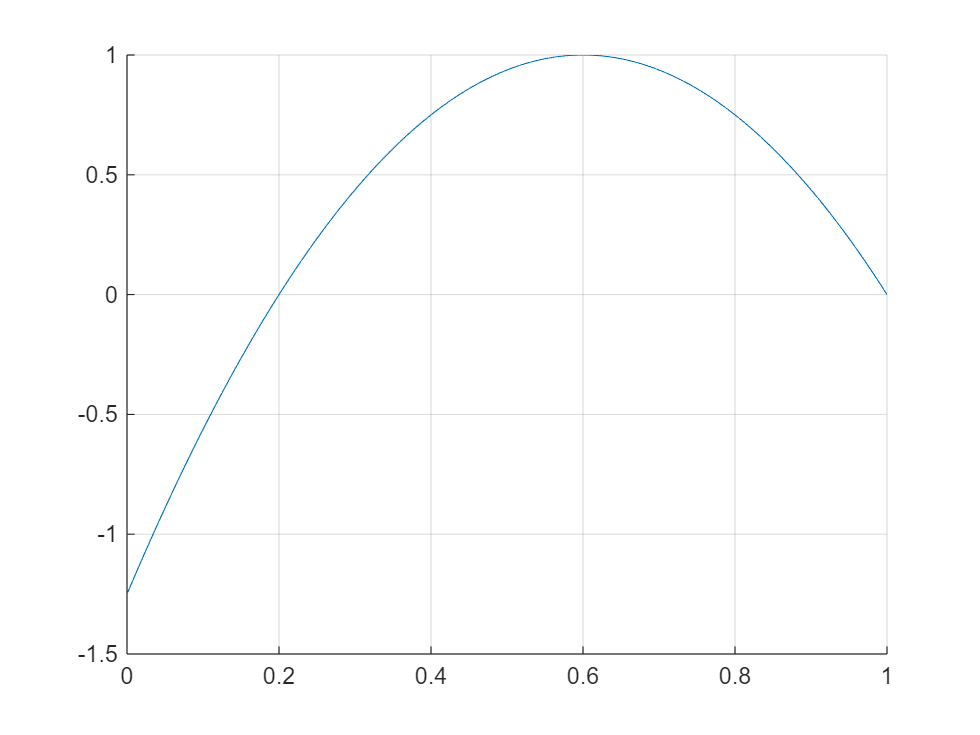

mu_val = 0.6; 

a = double(subs(sol.a, mu, mu_val)); 
b = double(subs(sol.b, mu, mu_val)); 
c = double(subs(sol.c, mu, mu_val)); 

hspan = 0 : 1E-3 : 1; 
clf; 
hold on; 
grid on; 
plot(hspan, a*hspan.^2+b*hspan+c); 
hold off; 